# Hands-On -  AR(1)  Stochastic Process: The Case of Non-Zero Mean White Noise

## Introduction

Consider the process


$$v(t) = a \, v(t-1) +  \eta(t) \qquad \eta(\cdot) \sim WN(\bar \eta,\lambda^2)$$


Recalling that $\vert a \vert <1$  and setting $\text{E} \left[ v(t) \right] = \bar v$ 


$$\bar v = \frac{\bar \eta}{1-a} \qquad \Longleftrightarrow \qquad  \bar v = W(1) \cdot \bar{\eta} \qquad W(z) = \displaystyle \frac{z}{z-a}$$


The **covariance function** 


$$\gamma_{v\,v}(\tau) = \text{cov}\big[ v(t) \cdot v(t-\tau) \big] = \text{E} \Big\{ \big[ v(t) - \bar{v} \big] \cdot \big[ v(t-\tau) - \bar{v}  \big]  \Big\}$$


coincides with the correlation funciton of the zero-mean process $\tilde{v}(t) := v(t)-\bar{v}$


$$\gamma_{v\,v}(\tau) = \text{cov}\big[ v(t) \cdot v(t-\tau) \big] = \text{E} \Big\{ \big[ v(t) - \bar{v} \big] \cdot \big[ v(t-\tau) - \bar{v}  \big]  \Big\} =  \text{E} \big\{  \tilde{v}(t) \cdot \tilde{v}(t-\tau)  \big\} = \gamma_{\tilde{v}\, \tilde{v}} (\tau)$$


## Sampled Estimator of the Mean Value, the Variance and the Autocorrelation Function

We have already analysed the sampled estimators of mean value and variance. We recall them for convenience.

### Sample Average Estimator 

Given $N$ random variables $\, v(1)\,,\; v(2)\,,\; \ldots\,,\; v(N) \,$such that


$$\text{E} \left[ v(i) \right] = \mu_v\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  v(i) - \mu_v \right] \, \left[ v(j) - \mu_v \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **sampled-average estimator**					

				
$$\hat{\mu}_{v} = \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} v(i) $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\mu_{v}}\right] = \mu_{v}$$


### The Sample Variance

The sample variance of $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with known mean $\mu_v$ is defined as 


$$ \hat \sigma^2_{\mu_v,N}={\frac {1}{N}}\sum _{i=1}^{N}(v_{i}-\mu_v)^2.$$


We have added the subindex $\mu$ to indicate that we used the exact value of the mean to calculate the variance. 

In practice, **the mean value is often unknown** and replaced by the sample mean. In that case the sample variance is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(v_{i}-\hat \mu_N)^2$$


### The Sample Autocorrelation Function

Given $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with **null mean value** $\mu_v = \text{E}\left[ v_i \right] = 0 \; \forall i$, the autocorrelation function $\gamma_{v}(\tau)$ can be estimated by mean of the following expression


$$\hat{\gamma}_v (\tau) = \left\{ \begin{array}{lcl}
\displaystyle \frac{1}{N-\tau} \sum_{n=0}^{N-\tau-1}\, v(n)\cdot v(n+\tau) & \quad & \tau \ge 0 \\
\hat{\gamma}_v(-\tau) & \quad & \tau <0
\end{array} \right. \qquad \left| \tau \right| \le N-1$$


It can be proven that it is an **unbiased estimator **(refer to [1] for details). Moreover, it can be proven that the variance of the estimate converges to zero as $N \to \infty$, so the estimate $\hat{\gamma}(\tau)$ is a **consistent estimate** of $\gamma(\tau)$ (refer to [1] for details).

## Estimated Autocovariance Function from Data

Let us generate $N$ samples of a WSS stationary AR(1) stochastic process.

Collect the data and then apply the sampled estimators.

clear variables
close all
clc

### Generate and Collect the Samples

Remember


$$AR(1) \, \colon \quad
v(t) = a \, v(t-1) +  \eta(t)$$


Ndata = 50000;    % select how many samples to collect and store

meanWG = 4.75; % the mean value of the noise eta(t)

varWG = 3.5;      % select the white noise variance

AR1 = zeros(Ndata,1);    % preallocating the store for the samples for the "v(t)" array for the 1st AR process

a_AR = 0.96;     % select the value of the AR coeff. a


### The AR(1) process

Let's generate the data from the AR(1) process

% the AR processes
Nbuffer = 1500; 
buffer = zeros(Nbuffer,1); % a buffer used to generate a stationary AR process, regardless of any possible initial condition
buffer(1) = randn;     % the initial condition for both the AR processes

eta = meanWG + sqrt(varWG)*randn(Ndata+Nbuffer,1); % let's generate the white noise samples

ARbuffer = [buffer; AR1]; % merging the arrays
N = numel(ARbuffer); % how many data to be computed?

% ---- the 1st AR(1) process ----
for ii = 2:N
    ARbuffer(ii) = a_AR * ARbuffer(ii-1)+eta(ii);
end % for ii

AR1 = ARbuffer(Nbuffer+1:end);



Let's estimate the mean value and the variance for the first AR process

av_valAR1 = mean(AR1)      % the average value for the 1st MA process

av_valAR1 = 118.6534

The theoretical mean value $\bar{v}$ is $\bar v = W(1) \cdot \bar{\eta} \qquad W(z) = \displaystyle \frac{z}{z-a}$

staticGain = 1/(1-a_AR);
theor_meanVal = staticGain * meanWG % the theoretical mean value

theor_meanVal = 118.7500


varAR1 = varWG/(1-a_AR.^2) % the variance of the AR1 stationary process of tilde_v

varAR1 = 44.6429

sampled_varAR1 = var(AR1)  % the sampled variance

sampled_varAR1 = 44.7735

Evaluate $\tilde{v}(t) = v(t)-\bar{v}$

AR0 = AR1-theor_meanVal; % the AR process with zero-mean

% check the average value of the zero-mean AR
av_AR0 = mean(AR0)

av_AR0 = -0.0966


% check the variance
sampled_varAR0 = var(AR0)  % the sampled variance

sampled_varAR0 = 44.7735

What is the theoretical value for the variance of the AR process $\tilde{v}(t)$?

Run more than once, varying the variance of the process. Observe the convergence of the sampled estimates of the mean vakue and the variance to the effective values, when increasing the number of collected data.

### **What About the Autocovariance Function?**

Ncorr1 =1024; % select the max value of tau in the estimation formula

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr1 <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcov().`

Have a look to the command input and output variables, and to some application examples, using 

[gamma_v1, lags_v1] = xcov(AR1, Ncorr1,'unbiased'); 
% unbiased estimation of the autocovariance function

[gamma_v0, lags_v0] = xcorr(AR0, Ncorr1,'unbiased'); 
% unbiased estimation of the autocorr. function of tilde_v

gammaAR1 = varAR1*(a_AR.^(abs(lags_v1))); % the true autocorrelation function of tilde_v


Now let's plot 

- the acquired samples of the AR(1) process

- the samples of the estimated autocovaraiance and autocorrelation function toghethere with the corresponding values of the theoretical expression of the autocovariance function

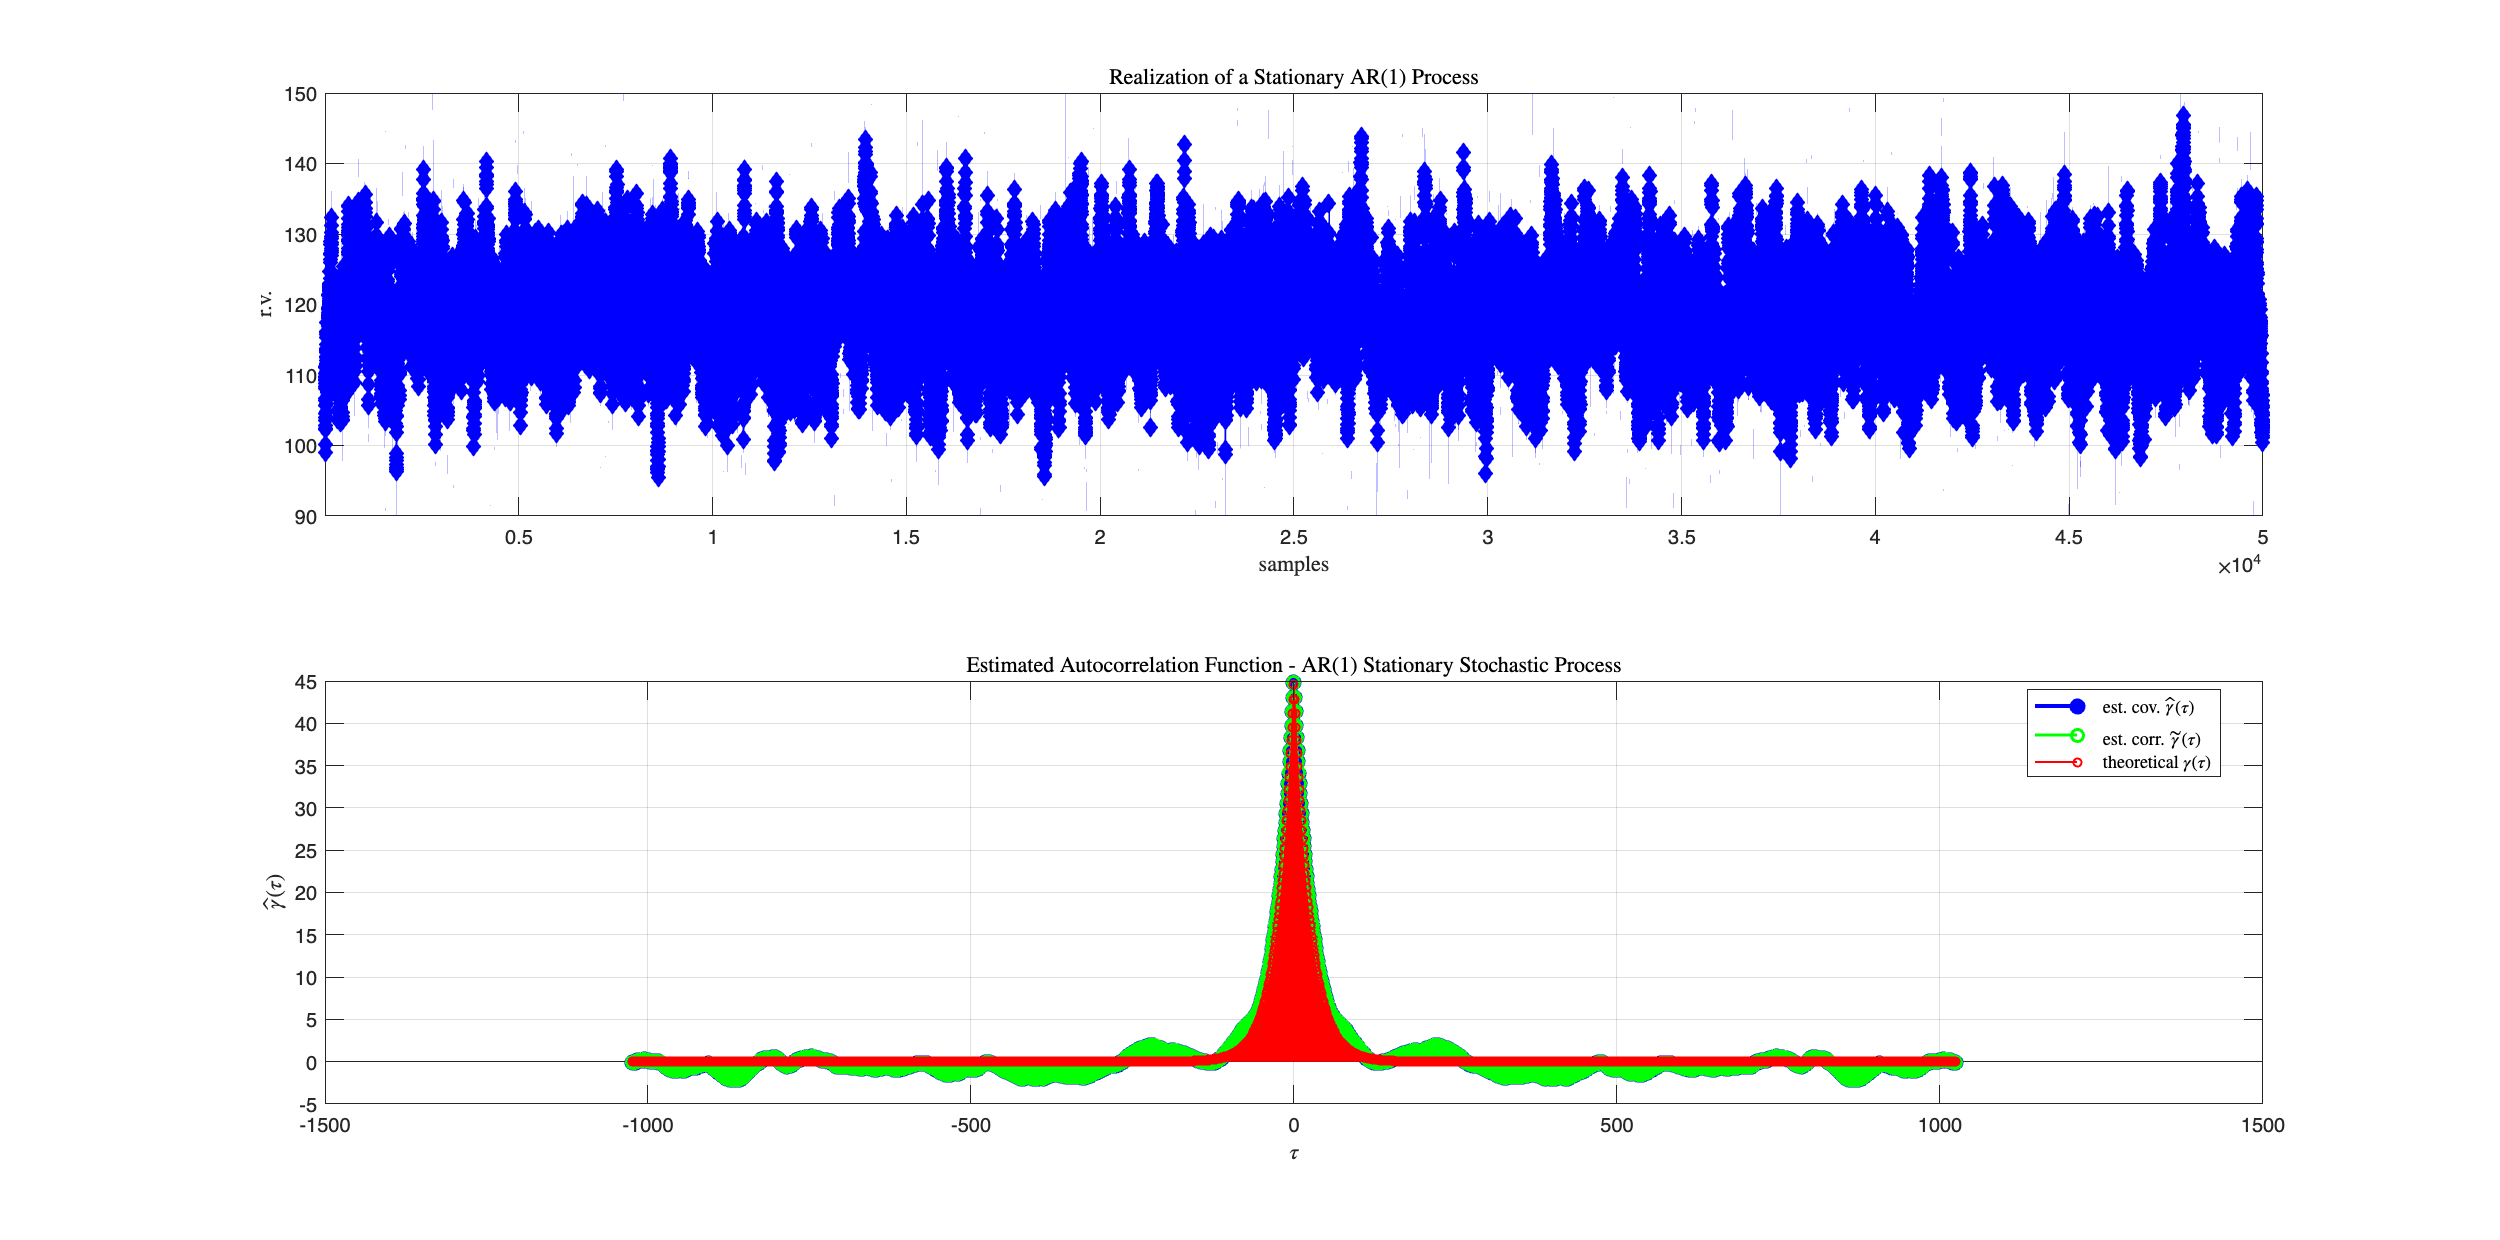

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(2,1,1);
plot(AR1,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary AR$(1)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis[']]]=

subplot(2,1,2);
% the covariance function of v(t)
stem(lags_v1, gamma_v1,'b','filled', 'LineWidth',2);
grid on; hold on;

% the correlation function of tilde_v
stem(lags_v0, gamma_v0,'g', 'LineWidth',1.5);

% the theoretical expression of the covaraince function
stem(lags_v1, gammaAR1, 'r', 'MarkerSize',4,'LineWidth',1.0);
xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - AR$(1)$ Stationary Stochastic Process',...
    'Interpreter','latex');
legend('est. cov. $\hat{\gamma}(\tau)$', 'est. corr. $\tilde{\gamma}(\tau)$','theoretical $\gamma(\tau)$', 'Location', 'best', 'Interpreter', 'latex')

## Estimation of the Spectral Power Density from Data 

So far, we estimated the average value, the variance of the r.v. of the process and the autocorrelation function, just using the collected data. What about the **spectrum**?

Given the samples of the estimated autocorrelation function $\hat{\gamma}(\tau)$, the **estimate of the spectrum** can be evaluate  according to the so-called ***"periodogram"***** algorithm**

### Spectral Power Density Estimation: the Periodogram - A Recap

Given $2N-1$ samples of the autocorrelation function $\hat{\gamma}(\tau)\,,\quad \tau = -N+1\,,\; -N+2\,,\; \ldots\, N-2\,,\; N-1$, where $N$is the number of collected samples of the r.v.

- the Fourier transform of the autocorrelation function estimate is

$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$    (++)

- by substituting into $\hat{\Gamma}(\omega)$ the expression of $\hat{\gamma}(\tau)$ as function of the samples $v(n)$, and taking into account the properties of the autocorrelation function (the correlation function is an even function), the estimate $\hat{\Gamma}(\omega)$ can also be expressed as

$\hat{\Gamma}(\omega) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} \right\vert^{2} = \displaystyle \frac{1}{N}  \left\vert \hat{V}(\omega) \right\vert^{2} $  where $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $    (*)

- It can be proven  that the expected value of the estimated spectrum is a **smoothed version of the true spectrum**. Moreover, it suffers from the same **spectral leakage problems** which are due to the finite number of data points (refer to [1] for details). Hence **the periodogram is not a consistent estimate** of the true power density spectrum.

- Over the years, many other methods have been proposed, with the aim of obtaining a consistent estimate of the power spectrum, but these algorithms are outside the scope of this live script (and these topics are not included in the course). For details, please refer to a textbook on "Digital Signal Processing" such as [1].

#### The Algorithm: Using the DFT in Power Spectrum Estimation

- given $N$ samples of the r.v. $v$, evaluate $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $, using the DFT algorithm, or more efficiently the FFT algorithm;


$$\hat{\Gamma}\left( 2\pi \displaystyle \frac{k}{N} \right) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\,2 \pi \,n\,\frac{k}{N}} \right\vert^{2} \qquad k = 0\,,\;1\,,\;2\,,\;\ldots N-1$$


#### The Spectrum of the AR Process

Given the samples, collected in the `array AR1`, let's apply the Eq. (++) to estimate the spectrum:

- Evaluate the DFT of the autocorrelation function estimate sequence

AR1_FFT = fftshift(fft(gamma_v1));   % compute the FFT of 
                                     % the autocorrelation function samples
                                     % sequence

% rearrange the array of the FFT, by shifting 
% the zero-frequency component to the 
% center of the array.

- Compute the power spectrum estimate according to Eq. (++)


$$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$$


**Proposal**: perform the spectrum estimation according to Eq. (*) [the periodogram] and compare the results.

powerSpectrumAR1 = abs(AR1_FFT); 
% the squared magnitude of the Fourier transform


- Compute the corresponding angular frequencies

omegaPSD1 = linspace(-pi,pi,numel(gamma_v1)); 
% (2 pi)/Ndata is the angular frequency resolution for the spectrum
PSDtrue = varWG./(1+a_AR.^2-2*a_AR*cos(omegaPSD1)); 
% the theoretical spectrum, evaluated at the angular frequencies in omegaPSD1

- plotting the spectrum and compare with the theoretical expression $\Gamma_{vv}(\omega) = \frac{\lambda^2}{
\left (1+a^2- 2 a \cos \omega \right )}
\qquad
\forall \, \omega \in [-\pi,\pi] \quad (\vert a \vert < 1)$

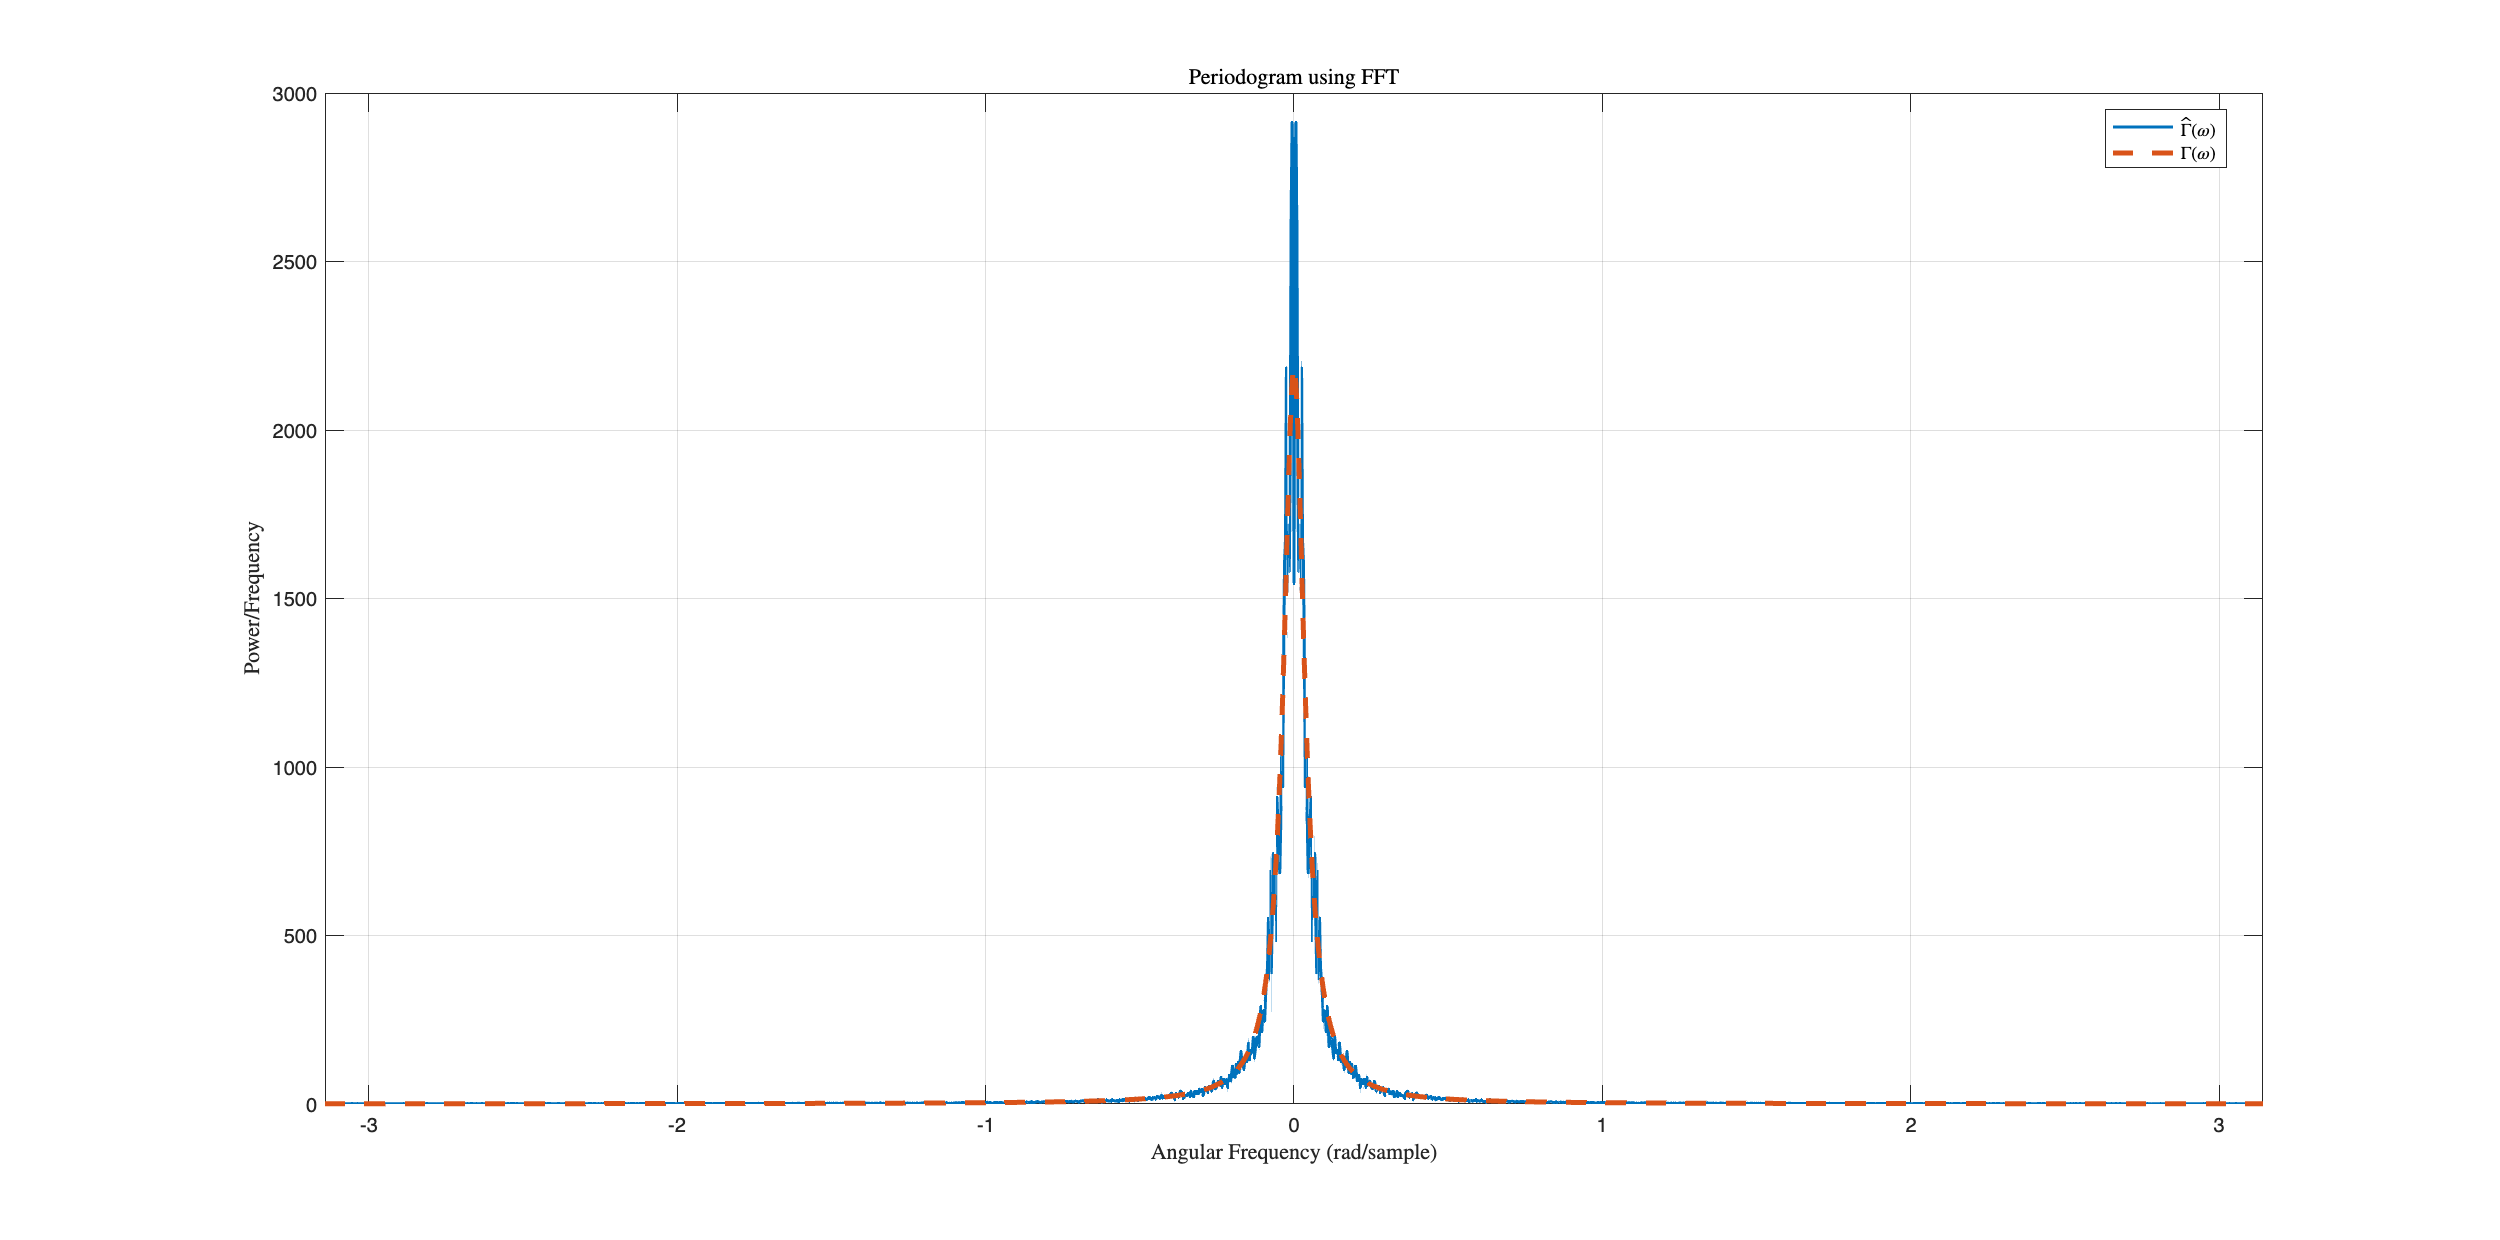

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSD1,powerSpectrumAR1, 'LineStyle','-','LineWidth',1.5); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on; hold on;
plot(omegaPSD1,PSDtrue, 'LineStyle','--','LineWidth',2.5); % the estimated PSD
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');
legend('$\hat{\Gamma}(\omega)$', '$\Gamma(\omega)$', 'Location','best', 'Interpreter', 'latex')

#### **Remark**

As written above, the periodogram is an estimate that can be very rough. Compare with the theoretical spectrum.

## References

[1] Proakis, John G. and Manolakis, Dimitris K.  * Digital Signal Processing (3rd Edition),* Prentice Hall,  1996.  